# Lorentz

## 6.4 CP11

med h = 0.001 og alle massene lik 5

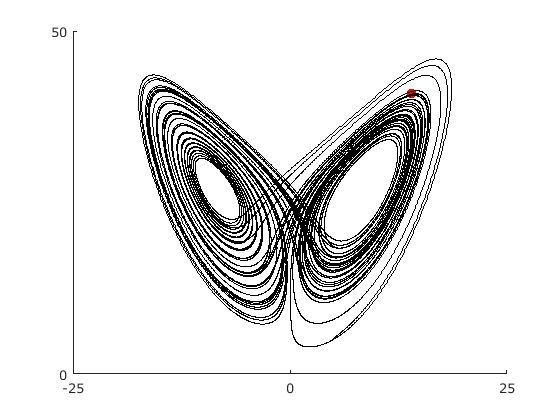

T = 50;
n = round(T*(1/0.001));
orbit([0,T],[5,5,5],n,500,50,1,@rk4step, @lorentz)

function orbit(inter,ic,n,p, scale, numBodies, step, slope)
%ORBIT Plotting FUNCTION for ANY m-body problem
%       inter: interval in time
%       initial conditions ic:
%       [xi vxi yi vyi ...]
%       n: number of steps
%       p: steps per point plotted
%       step: RK step function (e.g. Euler)
%       slope: equation iterator

h=(inter(2)-inter(1))/n; % plot n points
y(1,:)=ic;
t = linspace(inter(1), inter(2), n+1);
t(1)=inter(1); % build y vector


set(gca,'XLim',[-scale/2 scale/2],'YLim',[0 scale], ...
        'XTick',[-scale/2 0 scale/2],'YTick',[-scale 0 scale], ...
        'SortMethod','childorder','Visible','on');
cla;

% Set up body points
for i=1:numBodies
    heads(i)=line('color','r','Marker','.','markersize',25,...
          'xdata',[],'ydata',[]);
    tails(i)=line('color','b','LineStyle','-', ...
          'xdata',[],'ydata',[]);
    lines(i) = animatedline();
end

%[px,py]=ginput(1);% include these three lines
%[px1,py1]=ginput(1);% to enable mouse support
%y(1,:)=[px px1-px py py1-py];% 2 clicks set direction

hold on;

for k=1:n/p
    for i=1:p
        y(i+1,:)=step(t(i),y(i,:),h, slope);
    end
    % overwrite previous results
    y(1,:)=y(p+1,:);
    t(1)=t(p+1);
    
    % add data to each individual body
    % spaced at (i-1)*4 into the array
    for i=1:numBodies
        a = (i - 1)*4;
        set(heads(i),'xdata',y(1,1+a),'ydata',y(1,3+a))
        set(tails(i),'xdata',y(2:p,1+a),'ydata',y(2:p,3+a))
        addpoints(lines(i), y(2:p,1+a), y(2:p,3+a));
    end
    drawnow;
end

hold off;

end

function y=rk4step(t,w,h,ydot)
%one step of the Runge-Kutta order 4 method
s1=ydot(t,w);
s2=ydot(t+h/2,w+h.*s1./2);
s3=ydot(t+h/2,w+h.*s2./2);
s4=ydot(t+h,w+h.*s3);
y=w+h.*(s1+2*s2+2*s3+s4)./6;
end

function z=lorentz(~,y)
%Lorenz equations
s=10; r=28; b=8/3;
z(1)=-s.*y(1)+s.*y(2);
z(2)=-y(1).*y(3)+r.*y(1)-y(2);
z(3)=y(1).*y(2)-b.*y(3);
end